# Cowell's Method - Leonardo Russo 2015563

clear all
close all
clc

addpath("Library\")

savechoice = 1;

## Introduction to Known Parameters

The initial conditions for a selection of known orbits are defined. For each orbit, the initial position vector `r0` and the initial velocity vector `v0` are given. Additionally, user-defined initial conditions can be specified either directly as position and velocity vectors or via classical orbital elements (COEs).

muE = 398600.4415;          % km^3/s^2
rE = 6378.1363;             % km
D_sid = 86164;              % s
D_sol = 86400;              % s

days = 1;       % assuming  tf = t0 + n° days

% Define the Time Domain
t0 = 0;
tf = t0 + 1 * D_sol;

% Initial Conditions contain position and velocity vectors

r0_GPS = [13462.726354, -20645.023752, 10108.071628]';
v0_GPS = [2.638622 ,0.329454, -2.805018]';
IC_GPS = [r0_GPS; v0_GPS];

r0_Mol = [2869.944136, -1656.963019, -6617.757380]';
v0_Mol = [4.814217, 8.338469, 0.0]';
IC_Mol = [r0_Mol; v0_Mol];

r0_Geo = [-29260.792529, 23865.119693, 23865.119693]';
v0_Geo = [-2.334835, -1.212853, -1.212853]';
IC_Geo = [r0_Geo; v0_Geo];

% New Initial Conditions
r0_1 = [-9260.792529, 23865.119693, 23865.119693]';
v0_1 = [-2.334835, -1.212853, -1.212853]';
IC_1 = [r0_Geo; v0_Geo];

% New Initial Conditions via COE = [a e i Omega omega nu0]
a = rE + 10000;         % km
e = 0.5;
incl = deg2rad(40);     % rad
Omega = deg2rad(26);    % rad
omega = deg2rad(1);     % rad
nu0 = deg2rad(0);       % rad

COE1 = [a, e, incl, Omega, omega, nu0];

if e > 1
    error('Eccentricity in greater than one!')
end

## Propagation of the Trajectory

The propagation is obtained by solving the ordinary differential equations through the `ode113` function with the provided options.

% Initial Conditions
X0 = [r0_Mol; v0_Mol];

% Defining the options for the Integration
Tol0 = 1e-11;
Tol1 = 1e-13;
MaxStep = 60;
options = odeset('RelTol', Tol0, 'AbsTol',Tol1, 'MaxStep', MaxStep);

[tspan, Xsol] = ode113('DynamicalModel', [t0, tf], [X0; muE], options);

X = Xsol(:, 1:6);
x = X(:, 1);
y = X(:, 2);
z = X(:, 3);
u = X(:, 4);
v = X(:, 5);
w = X(:, 6);

rMatrixECI = [x, y, z];

## Visualization

The propagated trajectory is finally shown in 3D. 

Optionally, the plots can be saved as .jpg files by modifying the initial variable `savechoice`.

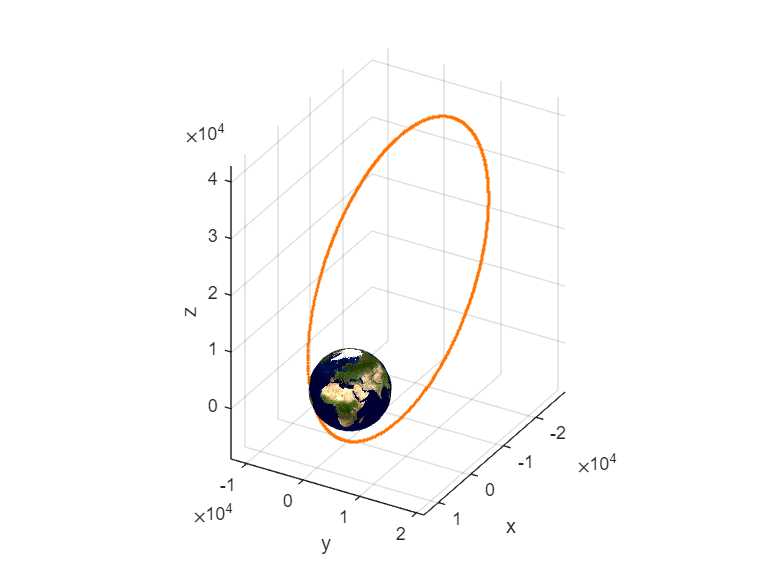

figure('Name', 'Trajectory Representation in 3D')
DrawTraj3D(rMatrixECI)

if savechoice
    saveas(gcf,'Propagated Trajectory.jpg')
end